# PIPPET simulations for manuscript

## Phase response for fixed C

Expecting four evenly spaced events, equally. Plots are based on the assumption that each event is reached with identical phase uncertainty.

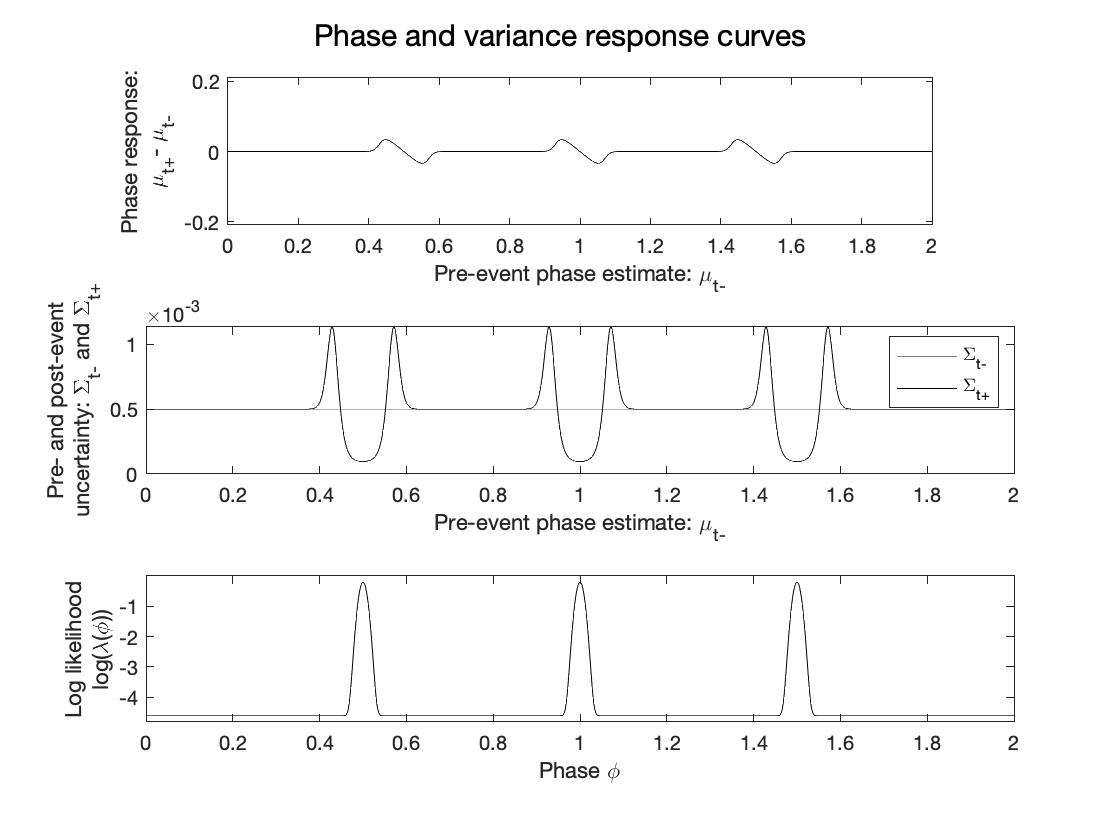

params = PIPPET_params(...
    'means_unit', [.5],...
    'expected_period', .5,...
    'variance_unit', [.0001],...
    'lambda_unit', [.02],...
    'expected_cycles', 3,...
    'event_times', []);

% lambda_0 = .00000001;
x_list = 0:.002:2;

C = .0005;

mu_list = zeros(size(x_list));
C_list = zeros(size(x_list));
for i = 1:length(x_list)
    mu_list(i) = params.streams{1}.mu_bar(x_list(i), C);
    C_list(i) = params.streams{1}.Pi_bar(x_list(i), C) - mu_list(i)^2;
end

PRC = mu_list - x_list;

figure()
subplot(3,1,1)
plot(x_list, PRC, 'k')
xlim([min(x_list), max(x_list)])
%axis equal
ylabel({'Phase response:';'\mu_{t+}- \mu_{t-}'})
xlabel({'Pre-event phase estimate: \mu_{t-}'})
axis('equal')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,2)
plot(x_list, zeros(size(x_list))+C, 'color', [.5,.5,.5])
hold on

plot(x_list, C_list, 'k')
ylabel({'Pre- and post-event';'uncertainty: \Sigma_{t-} and \Sigma_{t+}'})
xlabel({'Pre-event phase estimate: \mu_{t-}'})
legend('\Sigma_{t-}','\Sigma_{t+}')
%set(get(gca, "YLabel"), 'Rotation', 0)

subplot(3,1,3)
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
ylabel({'Log likelihood';'log(\lambda(\phi))'})
xlabel('Phase \phi')
ylim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])
%set(get(gca, "YLabel"), 'Rotation', 0)

sgtitle('Phase and variance response curves')

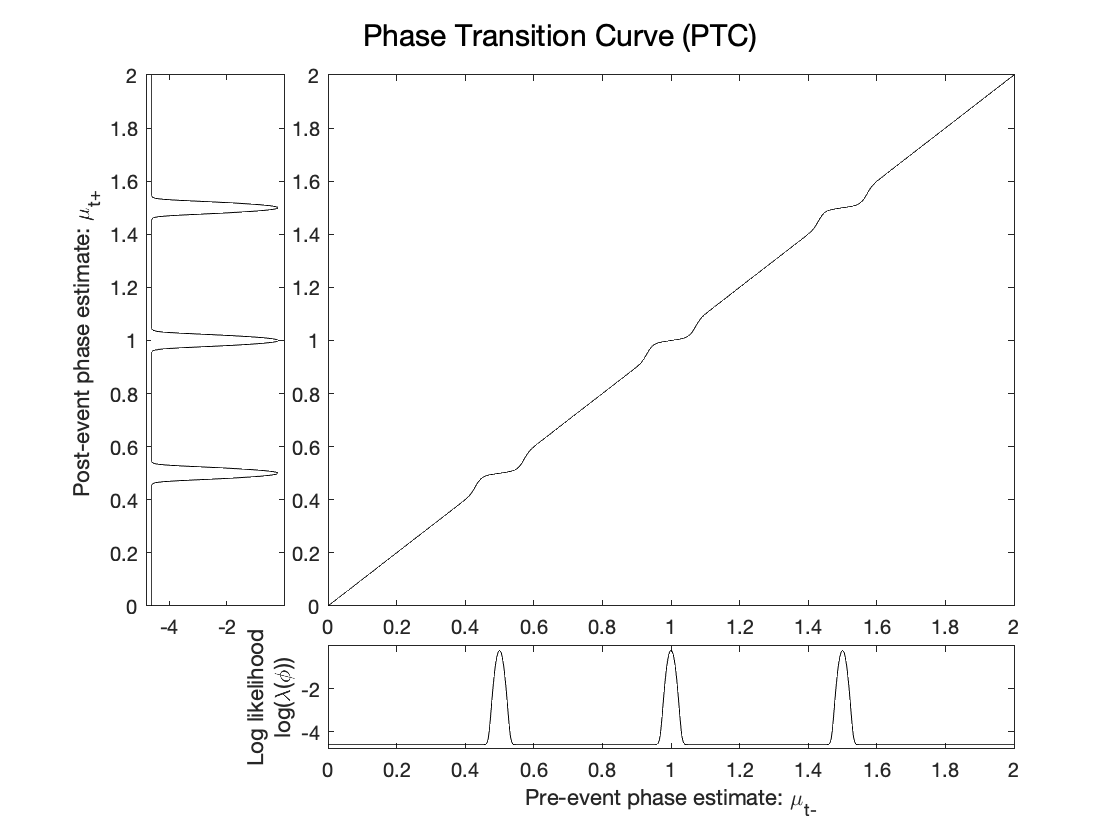


figure()

subplot(5,5, [2,3,4,5, 7,8,9,10, 12,13,14,15, 17,18,19,20])
plot(x_list, mu_list, 'k')
xlim([min(x_list), max(x_list)])
ylim([min(x_list), max(x_list)])

subplot(5,5, [1,6,11,16])
plot(log(params.streams{1}.expect_func(x_list)), x_list, 'k')
ylabel('Post-event phase estimate: \mu_{t+} ')
xlim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])


subplot(5,5, [22,23,24,25])
plot(x_list, log(params.streams{1}.expect_func(x_list)), 'k')
xlabel('Pre-event phase estimate: \mu_{t-}')
ylim([min(log(params.streams{1}.expect_func(x_list)))-.2, max(log(params.streams{1}.expect_func(x_list)))+.2])
ylabel({'Log likelihood';'log(\lambda(\phi))'})

sgtitle('Phase Transition Curve (PTC)')

## Time warping

What happens with strong expectations when nothing happens, as compared to when expectations are met? Time dilation!



params = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[.25, .5,.75, 1],...
    'title', 'Strong expectations fulfilled');
[mu_list, C_list] = run_PIPPET(params);

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.9000e-06

dC_1 = 4.9000e-06

dC_2 = 4.8999e-06

dC_1 = 4.9000e-06

dC_2 = 4.8999e-06

dC_1 = 4.9000e-06

dC_2 = 4.8999e-06

dC_1 = 4.9000e-06

dC_2 = 4.8999e-06

dC_1 = 4.9000e-06

dC_2 = 4.8998e-06

dC_1 = 4.9000e-06

dC_2 = 4.8998e-06

dC_1 = 4.9000e-06

dC_2 = 4.8997e-06

dC_1 = 4.9000e-06

dC_2 = 4.8996e-06

dC_1 = 4.9000e-06

dC_2 = 4.8995e-06

dC_1 = 4.9000e-06

dC_2 = 4.8993e-06

dC_1 = 4.9000e-06

dC_2 = 4.8992e-06

dC_1 = 4.9000e-06

dC_2 = 4.8989e-06

dC_1 = 4.9000e-06

dC_2 = 4.8987e-06

dC_1 = 4.9000e-06

dC_2 = 4.8983e-06

dC_1 = 4.9000e-06

dC_2 = 4.8979e-06

dC_1 = 4.9000e-06

dC_2 = 4.8973e-06

dC_1 = 4.9000e-06

dC_2 = 4.8967e-06

dC_1 = 4.9000e-06

dC_2 = 4.8959e-06

dC_1 = 4.9000e-06

dC_2 = 4.8949e-06

dC_1 = 4.9000e-06

dC_2 = 4.8937e-06

dC_1 = 4.9000e-06

dC_2 = 4.8923e-06

dC_1 = 4.9000e-06

dC_2 = 4.8905e-06

dC_1 = 4.9000e-06

dC_2 = 4.8885e-06

dC_1 = 4.9000e-06

dC_2 = 4.8860e-06

dC_1 = 4.9000e-06

dC_2 = 4.8831e-06

dC_1 = 4.9000e-06

dC_2 = 4.8797e-06

dC_1 = 4.9000e-06

dC_2 = 4.8756e-06

dC_1 = 4.9000e-06

dC_2 = 4.8708e-06

dC_1 = 4.9000e-06

dC_2 = 4.8652e-06

dC_1 = 4.9000e-06

dC_2 = 4.8587e-06

dC_1 = 4.9000e-06

dC_2 = 4.8511e-06

dC_1 = 4.9000e-06

dC_2 = 4.8424e-06

dC_1 = 4.9000e-06

dC_2 = 4.8322e-06

dC_1 = 4.9000e-06

dC_2 = 4.8206e-06

dC_1 = 4.9000e-06

dC_2 = 4.8072e-06

dC_1 = 4.9000e-06

dC_2 = 4.7919e-06

dC_1 = 4.9000e-06

dC_2 = 4.7745e-06

dC_1 = 4.9000e-06

dC_2 = 4.7548e-06

dC_1 = 4.9000e-06

dC_2 = 4.7325e-06

dC_1 = 4.9000e-06

dC_2 = 4.7073e-06

dC_1 = 4.9000e-06

dC_2 = 4.6790e-06

dC_1 = 4.9000e-06

dC_2 = 4.6474e-06

dC_1 = 4.9000e-06

dC_2 = 4.6120e-06

dC_1 = 4.9000e-06

dC_2 = 4.5727e-06

dC_1 = 4.9000e-06

dC_2 = 4.5291e-06

dC_1 = 4.9000e-06

dC_2 = 4.4810e-06

dC_1 = 4.9000e-06

dC_2 = 4.4279e-06

dC_1 = 4.9000e-06

dC_2 = 4.3697e-06

dC_1 = 4.9000e-06

dC_2 = 4.3059e-06

dC_1 = 4.9000e-06

dC_2 = 4.2364e-06

dC_1 = 4.9000e-06

dC_2 = 4.1609e-06

dC_1 = 4.9000e-06

dC_2 = 4.0790e-06

dC_1 = 4.9000e-06

dC_2 = 3.9906e-06

dC_1 = 4.9000e-06

dC_2 = 3.8954e-06

dC_1 = 4.9000e-06

dC_2 = 3.7934e-06

dC_1 = 4.9000e-06

dC_2 = 3.6842e-06

dC_1 = 4.9000e-06

dC_2 = 3.5679e-06

dC_1 = 4.9000e-06

dC_2 = 3.4444e-06

dC_1 = 4.9000e-06

dC_2 = 3.3136e-06

dC_1 = 4.9000e-06

dC_2 = 3.1756e-06

dC_1 = 4.9000e-06

dC_2 = 3.0305e-06

dC_1 = 4.9000e-06

dC_2 = 2.8784e-06

dC_1 = 4.9000e-06

dC_2 = 2.7195e-06

dC_1 = 4.9000e-06

dC_2 = 2.5540e-06

dC_1 = 4.9000e-06

dC_2 = 2.3821e-06

dC_1 = 4.9000e-06

dC_2 = 2.2044e-06

dC_1 = 4.9000e-06

dC_2 = 2.0210e-06

dC_1 = 4.9000e-06

dC_2 = 1.8326e-06

dC_1 = 4.9000e-06

dC_2 = 1.6394e-06

dC_1 = 4.9000e-06

dC_2 = 1.4421e-06

dC_1 = 4.9000e-06

dC_2 = 1.2412e-06

dC_1 = 4.9000e-06

dC_2 = 1.0373e-06

dC_1 = 4.9000e-06

dC_2 = 8.3090e-07

dC_1 = 4.9000e-06

dC_2 = 6.2272e-07

dC_1 = 4.9000e-06

dC_2 = 4.1336e-07

dC_1 = 4.9000e-06

dC_2 = 2.0348e-07

dC_1 = 4.9000e-06

dC_2 = -6.2741e-09

dC_1 = 4.9000e-06

dC_2 = -2.1526e-07

dC_1 = 4.9000e-06

dC_2 = -4.2282e-07

dC_1 = 4.9000e-06

dC_2 = -6.2832e-07

dC_1 = 4.9000e-06

dC_2 = -8.3114e-07

dC_1 = 4.9000e-06

dC_2 = -1.0307e-06

dC_1 = 4.9000e-06

dC_2 = -1.2263e-06

dC_1 = 4.9000e-06

dC_2 = -1.4175e-06

dC_1 = 4.9000e-06

dC_2 = -1.6037e-06

dC_1 = 4.9000e-06

dC_2 = -1.7844e-06

dC_1 = 4.9000e-06

dC_2 = -1.9591e-06

dC_1 = 4.9000e-06

dC_2 = -2.1274e-06

dC_1 = 4.9000e-06

dC_2 = -2.2888e-06

dC_1 = 4.9000e-06

dC_2 = -2.4429e-06

dC_1 = 4.9000e-06

dC_2 = -2.5893e-06

dC_1 = 4.9000e-06

dC_2 = -2.7278e-06

dC_1 = 4.9000e-06

dC_2 = -2.8580e-06

dC_1 = 4.9000e-06

dC_2 = -2.9796e-06

dC_1 = 4.9000e-06

dC_2 = -3.0923e-06

dC_1 = 4.9000e-06

dC_2 = -3.1960e-06

dC_1 = 4.9000e-06

dC_2 = -3.2904e-06

dC_1 = 4.9000e-06

dC_2 = -3.3754e-06

dC_1 = 4.9000e-06

dC_2 = -3.4507e-06

dC_1 = 4.9000e-06

dC_2 = -3.5163e-06

dC_1 = 4.9000e-06

dC_2 = -3.5720e-06

dC_1 = 4.9000e-06

dC_2 = -3.6177e-06

dC_1 = 4.9000e-06

dC_2 = -3.6533e-06

dC_1 = 4.9000e-06

dC_2 = -3.6788e-06

dC_1 = 4.9000e-06

dC_2 = -3.6940e-06

dC_1 = 4.9000e-06

dC_2 = -3.6989e-06

dC_1 = 4.9000e-06

dC_2 = -3.6935e-06

dC_1 = 4.9000e-06

dC_2 = -3.6778e-06

dC_1 = 4.9000e-06

dC_2 = -3.6516e-06

dC_1 = 4.9000e-06

dC_2 = -3.6149e-06

dC_1 = 4.9000e-06

dC_2 = -3.5677e-06

dC_1 = 4.9000e-06

dC_2 = -3.5100e-06

dC_1 = 4.9000e-06

dC_2 = -3.4418e-06

dC_1 = 4.9000e-06

dC_2 = -3.3629e-06

dC_1 = 4.9000e-06

dC_2 = -3.2734e-06

dC_1 = 4.9000e-06

dC_2 = -3.1732e-06

dC_1 = 4.9000e-06

dC_2 = -3.0623e-06

dC_1 = 4.9000e-06

dC_2 = -2.9406e-06

dC_1 = 4.9000e-06

dC_2 = -2.8080e-06

dC_1 = 4.9000e-06

dC_2 = -2.6644e-06

dC_1 = 4.9000e-06

dC_2 = -2.5098e-06

dC_1 = 4.9000e-06

dC_2 = -2.3441e-06

dC_1 = 4.9000e-06

dC_2 = -2.1672e-06

dC_1 = 4.9000e-06

dC_2 = -1.9789e-06

dC_1 = 4.9000e-06

dC_2 = -1.7792e-06

dC_1 = 4.9000e-06

dC_2 = -1.5678e-06

dC_1 = 4.9000e-06

dC_2 = -1.3446e-06

dC_1 = 4.9000e-06

dC_2 = -1.1094e-06

dC_1 = 4.9000e-06

dC_2 = -8.6212e-07

dC_1 = 4.9000e-06

dC_2 = -6.0247e-07

dC_1 = 4.9000e-06

dC_2 = -3.3025e-07

dC_1 = 4.9000e-06

dC_2 = -4.5233e-08

dC_1 = 4.9000e-06

dC_2 = 2.5283e-07

dC_1 = 4.9000e-06

dC_2 = 5.6418e-07

dC_1 = 4.9000e-06

dC_2 = 8.8912e-07

dC_1 = 4.9000e-06

dC_2 = 1.2279e-06

dC_1 = 4.9000e-06

dC_2 = 1.5808e-06

dC_1 = 4.9000e-06

dC_2 = 1.9482e-06

dC_1 = 4.9000e-06

dC_2 = 2.3304e-06

dC_1 = 4.9000e-06

dC_2 = 2.7276e-06

dC_1 = 4.9000e-06

dC_2 = 3.1402e-06

dC_1 = 4.9000e-06

dC_2 = 3.5685e-06

dC_1 = 4.9000e-06

dC_2 = 4.0128e-06

dC_1 = 4.9000e-06

dC_2 = 4.4735e-06

dC_1 = 4.9000e-06

dC_2 = 4.9509e-06

dC_1 = 4.9000e-06

dC_2 = 5.4451e-06

dC_1 = 4.9000e-06

dC_2 = 5.9565e-06

dC_1 = 4.9000e-06

dC_2 = 6.4854e-06

dC_1 = 4.9000e-06

dC_2 = 7.0319e-06

dC_1 = 4.9000e-06

dC_2 = 7.5962e-06

dC_1 = 4.9000e-06

dC_2 = 8.1784e-06

dC_1 = 4.9000e-06

dC_2 = 8.7786e-06

dC_1 = 4.9000e-06

dC_2 = 9.3969e-06

dC_1 = 4.9000e-06

dC_2 = 1.0033e-05

dC_1 = 4.9000e-06

dC_2 = 1.0687e-05

dC_1 = 4.9000e-06

dC_2 = 1.1359e-05

dC_1 = 4.9000e-06

dC_2 = 1.2048e-05

dC_1 = 4.9000e-06

dC_2 = 7.4333e-06

dC_1 = 4.9000e-06

dC_2 = 7.7139e-06

dC_1 = 4.9000e-06

dC_2 = 7.9684e-06

dC_1 = 4.9000e-06

dC_2 = 8.1853e-06

dC_1 = 4.9000e-06

dC_2 = 8.3532e-06

dC_1 = 4.9000e-06

dC_2 = 8.4614e-06

dC_1 = 4.9000e-06

dC_2 = 8.5007e-06

dC_1 = 4.9000e-06

dC_2 = 8.4640e-06

dC_1 = 4.9000e-06

dC_2 = 8.3466e-06

dC_1 = 4.9000e-06

dC_2 = 8.1468e-06

dC_1 = 4.9000e-06

dC_2 = 7.8660e-06

dC_1 = 4.9000e-06

dC_2 = 7.5087e-06

dC_1 = 4.9000e-06

dC_2 = 7.0828e-06

dC_1 = 4.9000e-06

dC_2 = 6.5987e-06

dC_1 = 4.9000e-06

dC_2 = 6.0694e-06

dC_1 = 4.9000e-06

dC_2 = 5.5096e-06

dC_1 = 4.9000e-06

dC_2 = 4.9350e-06

dC_1 = 4.9000e-06

dC_2 = 4.3616e-06

dC_1 = 4.9000e-06

dC_2 = 3.8050e-06

dC_1 = 4.9000e-06

dC_2 = 3.2794e-06

dC_1 = 4.9000e-06

dC_2 = 2.7970e-06

dC_1 = 4.9000e-06

dC_2 = 2.3676e-06

dC_1 = 4.9000e-06

dC_2 = 1.9982e-06

dC_1 = 4.9000e-06

dC_2 = 1.6926e-06

dC_1 = 4.9000e-06

dC_2 = 1.4521e-06

dC_1 = 4.9000e-06

dC_2 = 1.2752e-06

dC_1 = 4.9000e-06

dC_2 = 1.1584e-06

dC_1 = 4.9000e-06

dC_2 = 1.0964e-06

dC_1 = 4.9000e-06

dC_2 = 1.0829e-06

dC_1 = 4.9000e-06

dC_2 = 1.1113e-06

dC_1 = 4.9000e-06

dC_2 = 1.1745e-06

dC_1 = 4.9000e-06

dC_2 = 1.2658e-06

dC_1 = 4.9000e-06

dC_2 = 1.3789e-06

dC_1 = 4.9000e-06

dC_2 = 1.5084e-06

dC_1 = 4.9000e-06

dC_2 = 1.6492e-06

dC_1 = 4.9000e-06

dC_2 = 1.7974e-06

dC_1 = 4.9000e-06

dC_2 = 1.9494e-06

dC_1 = 4.9000e-06

dC_2 = 2.1025e-06

dC_1 = 4.9000e-06

dC_2 = 2.2545e-06

dC_1 = 4.9000e-06

dC_2 = 2.4037e-06

dC_1 = 4.9000e-06

dC_2 = 2.5489e-06

dC_1 = 4.9000e-06

dC_2 = 2.6891e-06

dC_1 = 4.9000e-06

dC_2 = 2.8238e-06

dC_1 = 4.9000e-06

dC_2 = 2.9525e-06

dC_1 = 4.9000e-06

dC_2 = 3.0750e-06

dC_1 = 4.9000e-06

dC_2 = 3.1912e-06

dC_1 = 4.9000e-06

dC_2 = 3.3012e-06

dC_1 = 4.9000e-06

dC_2 = 3.4051e-06

dC_1 = 4.9000e-06

dC_2 = 3.5030e-06

dC_1 = 4.9000e-06

dC_2 = 3.5951e-06

dC_1 = 4.9000e-06

dC_2 = 3.6817e-06

dC_1 = 4.9000e-06

dC_2 = 3.7630e-06

dC_1 = 4.9000e-06

dC_2 = 3.8392e-06

dC_1 = 4.9000e-06

dC_2 = 3.9106e-06

dC_1 = 4.9000e-06

dC_2 = 3.9776e-06

dC_1 = 4.9000e-06

dC_2 = 4.0402e-06

dC_1 = 4.9000e-06

dC_2 = 4.0988e-06

dC_1 = 4.9000e-06

dC_2 = 4.1537e-06

dC_1 = 4.9000e-06

dC_2 = 4.2049e-06

dC_1 = 4.9000e-06

dC_2 = 4.2528e-06

dC_1 = 4.9000e-06

dC_2 = 4.2976e-06

dC_1 = 4.9000e-06

dC_2 = 4.3394e-06

dC_1 = 4.9000e-06

dC_2 = 4.3784e-06

dC_1 = 4.9000e-06

dC_2 = 4.4148e-06

dC_1 = 4.9000e-06

dC_2 = 4.4488e-06

dC_1 = 4.9000e-06

dC_2 = 4.4805e-06

dC_1 = 4.9000e-06

dC_2 = 4.5101e-06

dC_1 = 4.9000e-06

dC_2 = 4.5377e-06

dC_1 = 4.9000e-06

dC_2 = 4.5634e-06

dC_1 = 4.9000e-06

dC_2 = 4.5874e-06

dC_1 = 4.9000e-06

dC_2 = 4.6098e-06

dC_1 = 4.9000e-06

dC_2 = 4.6306e-06

dC_1 = 4.9000e-06

dC_2 = 4.6499e-06

dC_1 = 4.9000e-06

dC_2 = 4.6680e-06

dC_1 = 4.9000e-06

dC_2 = 4.6848e-06

dC_1 = 4.9000e-06

dC_2 = 4.7004e-06

dC_1 = 4.9000e-06

dC_2 = 4.7150e-06

dC_1 = 4.9000e-06

dC_2 = 4.7285e-06

dC_1 = 4.9000e-06

dC_2 = 4.7411e-06

dC_1 = 4.9000e-06

dC_2 = 4.7528e-06

dC_1 = 4.9000e-06

dC_2 = 4.7636e-06

dC_1 = 4.9000e-06

dC_2 = 4.7737e-06

dC_1 = 4.9000e-06

dC_2 = 4.7831e-06

dC_1 = 4.9000e-06

dC_2 = 4.7918e-06

dC_1 = 4.9000e-06

dC_2 = 4.7999e-06

dC_1 = 4.9000e-06

dC_2 = 4.8074e-06

dC_1 = 4.9000e-06

dC_2 = 4.8144e-06

dC_1 = 4.9000e-06

dC_2 = 4.8209e-06

dC_1 = 4.9000e-06

dC_2 = 4.8268e-06

dC_1 = 4.9000e-06

dC_2 = 4.8324e-06

dC_1 = 4.9000e-06

dC_2 = 4.8375e-06

dC_1 = 4.9000e-06

dC_2 = 4.8423e-06

dC_1 = 4.9000e-06

dC_2 = 4.8467e-06

dC_1 = 4.9000e-06

dC_2 = 4.8508e-06

dC_1 = 4.9000e-06

dC_2 = 4.8546e-06

dC_1 = 4.9000e-06

dC_2 = 4.8581e-06

dC_1 = 4.9000e-06

dC_2 = 4.8613e-06

dC_1 = 4.9000e-06

dC_2 = 4.8643e-06

dC_1 = 4.9000e-06

dC_2 = 4.8671e-06

dC_1 = 4.9000e-06

dC_2 = 4.8697e-06

dC_1 = 4.9000e-06

dC_2 = 4.8720e-06

dC_1 = 4.9000e-06

dC_2 = 4.8742e-06

dC_1 = 4.9000e-06

dC_2 = 4.8762e-06

dC_1 = 4.9000e-06

dC_2 = 4.8781e-06

dC_1 = 4.9000e-06

dC_2 = 4.8798e-06

dC_1 = 4.9000e-06

dC_2 = 4.8813e-06

dC_1 = 4.9000e-06

dC_2 = 4.8827e-06

dC_1 = 4.9000e-06

dC_2 = 4.8840e-06

dC_1 = 4.9000e-06

dC_2 = 4.8852e-06

dC_1 = 4.9000e-06

dC_2 = 4.8862e-06

dC_1 = 4.9000e-06

dC_2 = 4.8871e-06

dC_1 = 4.9000e-06

dC_2 = 4.8879e-06

dC_1 = 4.9000e-06

dC_2 = 4.8886e-06

dC_1 = 4.9000e-06

dC_2 = 4.8891e-06

dC_1 = 4.9000e-06

dC_2 = 4.8894e-06

dC_1 = 4.9000e-06

dC_2 = 4.8896e-06

dC_1 = 4.9000e-06

dC_2 = 4.8896e-06

dC_1 = 4.9000e-06

dC_2 = 4.8894e-06

dC_1 = 4.9000e-06

dC_2 = 4.8889e-06

dC_1 = 4.9000e-06

dC_2 = 4.8881e-06

dC_1 = 4.9000e-06

dC_2 = 4.8870e-06

dC_1 = 4.9000e-06

dC_2 = 4.8855e-06

dC_1 = 4.9000e-06

dC_2 = 4.8836e-06

dC_1 = 4.9000e-06

dC_2 = 4.8811e-06

dC_1 = 4.9000e-06

dC_2 = 4.8780e-06

dC_1 = 4.9000e-06

dC_2 = 4.8741e-06

dC_1 = 4.9000e-06

dC_2 = 4.8695e-06

dC_1 = 4.9000e-06

dC_2 = 4.8638e-06

dC_1 = 4.9000e-06

dC_2 = 4.8571e-06

dC_1 = 4.9000e-06

dC_2 = 4.8490e-06

dC_1 = 4.9000e-06

dC_2 = 4.8395e-06

dC_1 = 4.9000e-06

dC_2 = 4.8284e-06

dC_1 = 4.9000e-06

dC_2 = 4.8153e-06

dC_1 = 4.9000e-06

dC_2 = 4.8002e-06

dC_1 = 4.9000e-06

dC_2 = 4.7826e-06

dC_1 = 4.9000e-06

dC_2 = 4.7624e-06

dC_1 = 4.9000e-06

dC_2 = 4.7392e-06

dC_1 = 4.9000e-06

dC_2 = 4.7127e-06

dC_1 = 4.9000e-06

dC_2 = 4.6826e-06

dC_1 = 4.9000e-06

dC_2 = 4.6485e-06

dC_1 = 4.9000e-06

dC_2 = 4.6101e-06

dC_1 = 4.9000e-06

dC_2 = 4.5670e-06

dC_1 = 4.9000e-06

dC_2 = 4.5188e-06

dC_1 = 4.9000e-06

dC_2 = 4.4652e-06

dC_1 = 4.9000e-06

dC_2 = 4.4058e-06

dC_1 = 4.9000e-06

dC_2 = 4.3402e-06

dC_1 = 4.9000e-06

dC_2 = 4.2681e-06

dC_1 = 4.9000e-06

dC_2 = 4.1892e-06

dC_1 = 4.9000e-06

dC_2 = 4.1032e-06

dC_1 = 4.9000e-06

dC_2 = 4.0098e-06

dC_1 = 4.9000e-06

dC_2 = 3.9088e-06

dC_1 = 4.9000e-06

dC_2 = 3.8000e-06

dC_1 = 4.9000e-06

dC_2 = 3.6833e-06

dC_1 = 4.9000e-06

dC_2 = 3.5587e-06

dC_1 = 4.9000e-06

dC_2 = 3.4261e-06

dC_1 = 4.9000e-06

dC_2 = 3.2856e-06

dC_1 = 4.9000e-06

dC_2 = 3.1374e-06

dC_1 = 4.9000e-06

dC_2 = 2.9815e-06

dC_1 = 4.9000e-06

dC_2 = 2.8183e-06

dC_1 = 4.9000e-06

dC_2 = 2.6482e-06

dC_1 = 4.9000e-06

dC_2 = 2.4715e-06

dC_1 = 4.9000e-06

dC_2 = 2.2887e-06

dC_1 = 4.9000e-06

dC_2 = 2.1003e-06

dC_1 = 4.9000e-06

dC_2 = 1.9069e-06

dC_1 = 4.9000e-06

dC_2 = 1.7091e-06

dC_1 = 4.9000e-06

dC_2 = 1.5077e-06

dC_1 = 4.9000e-06

dC_2 = 1.3032e-06

dC_1 = 4.9000e-06

dC_2 = 1.0966e-06

dC_1 = 4.9000e-06

dC_2 = 8.8849e-07

dC_1 = 4.9000e-06

dC_2 = 6.7971e-07

dC_1 = 4.9000e-06

dC_2 = 4.7104e-07

dC_1 = 4.9000e-06

dC_2 = 2.6328e-07

dC_1 = 4.9000e-06

dC_2 = 5.7205e-08

dC_1 = 4.9000e-06

dC_2 = -1.4640e-07

dC_1 = 4.9000e-06

dC_2 = -3.4680e-07

dC_1 = 4.9000e-06

dC_2 = -5.4324e-07

dC_1 = 4.9000e-06

dC_2 = -7.3503e-07

dC_1 = 4.9000e-06

dC_2 = -9.2149e-07

dC_1 = 4.9000e-06

dC_2 = -1.1020e-06

dC_1 = 4.9000e-06

dC_2 = -1.2759e-06

dC_1 = 4.9000e-06

dC_2 = -1.4427e-06

dC_1 = 4.9000e-06

dC_2 = -1.6019e-06

dC_1 = 4.9000e-06

dC_2 = -1.7529e-06

dC_1 = 4.9000e-06

dC_2 = -1.8953e-06

dC_1 = 4.9000e-06

dC_2 = -2.0287e-06

dC_1 = 4.9000e-06

dC_2 = -2.1528e-06

dC_1 = 4.9000e-06

dC_2 = -2.2671e-06

dC_1 = 4.9000e-06

dC_2 = -2.3715e-06

dC_1 = 4.9000e-06

dC_2 = -2.4656e-06

dC_1 = 4.9000e-06

dC_2 = -2.5493e-06

dC_1 = 4.9000e-06

dC_2 = -2.6222e-06

dC_1 = 4.9000e-06

dC_2 = -2.6843e-06

dC_1 = 4.9000e-06

dC_2 = -2.7354e-06

dC_1 = 4.9000e-06

dC_2 = -2.7753e-06

dC_1 = 4.9000e-06

dC_2 = -2.8039e-06

dC_1 = 4.9000e-06

dC_2 = -2.8212e-06

dC_1 = 4.9000e-06

dC_2 = -2.8271e-06

dC_1 = 4.9000e-06

dC_2 = -2.8214e-06

dC_1 = 4.9000e-06

dC_2 = -2.8042e-06

dC_1 = 4.9000e-06

dC_2 = -2.7754e-06

dC_1 = 4.9000e-06

dC_2 = -2.7349e-06

dC_1 = 4.9000e-06

dC_2 = -2.6827e-06

dC_1 = 4.9000e-06

dC_2 = -2.6187e-06

dC_1 = 4.9000e-06

dC_2 = -2.5430e-06

dC_1 = 4.9000e-06

dC_2 = -2.4554e-06

dC_1 = 4.9000e-06

dC_2 = -2.3559e-06

dC_1 = 4.9000e-06

dC_2 = -2.2445e-06

dC_1 = 4.9000e-06

dC_2 = -2.1210e-06

dC_1 = 4.9000e-06

dC_2 = -1.9854e-06

dC_1 = 4.9000e-06

dC_2 = -1.8377e-06

dC_1 = 4.9000e-06

dC_2 = -1.6777e-06

dC_1 = 4.9000e-06

dC_2 = -1.5053e-06

dC_1 = 4.9000e-06

dC_2 = -1.3204e-06

dC_1 = 4.9000e-06

dC_2 = -1.1229e-06

dC_1 = 4.9000e-06

dC_2 = -9.1252e-07

dC_1 = 4.9000e-06

dC_2 = -6.8922e-07

dC_1 = 4.9000e-06

dC_2 = -4.5276e-07

dC_1 = 4.9000e-06

dC_2 = -2.0294e-07

dC_1 = 4.9000e-06

dC_2 = 6.0442e-08

dC_1 = 4.9000e-06

dC_2 = 3.3764e-07

dC_1 = 4.9000e-06

dC_2 = 6.2889e-07

dC_1 = 4.9000e-06

dC_2 = 9.3447e-07

dC_1 = 4.9000e-06

dC_2 = 1.2547e-06

dC_1 = 4.9000e-06

dC_2 = 1.5898e-06

dC_1 = 4.9000e-06

dC_2 = 1.9401e-06

dC_1 = 4.9000e-06

dC_2 = 2.3059e-06

dC_1 = 4.9000e-06

dC_2 = 2.6877e-06

dC_1 = 4.9000e-06

dC_2 = 3.0856e-06

dC_1 = 4.9000e-06

dC_2 = 3.5000e-06

dC_1 = 4.9000e-06

dC_2 = 3.9313e-06

dC_1 = 4.9000e-06

dC_2 = 4.3799e-06

dC_1 = 4.9000e-06

dC_2 = 4.8459e-06

dC_1 = 4.9000e-06

dC_2 = 5.3297e-06

dC_1 = 4.9000e-06

dC_2 = 5.8317e-06

dC_1 = 4.9000e-06

dC_2 = 6.3520e-06

dC_1 = 4.9000e-06

dC_2 = 6.8909e-06

dC_1 = 4.9000e-06

dC_2 = 7.4485e-06

dC_1 = 4.9000e-06

dC_2 = 8.0250e-06

dC_1 = 4.9000e-06

dC_2 = 8.6205e-06

dC_1 = 4.9000e-06

dC_2 = 9.2348e-06

dC_1 = 4.9000e-06

dC_2 = 9.8681e-06

dC_1 = 4.9000e-06

dC_2 = 1.0520e-05

dC_1 = 4.9000e-06

dC_2 = 1.1190e-05

dC_1 = 4.9000e-06

dC_2 = 1.1879e-05

dC_1 = 4.9000e-06

dC_2 = 1.2584e-05

dC_1 = 4.9000e-06

dC_2 = 1.3307e-05

dC_1 = 4.9000e-06

dC_2 = 1.4046e-05

dC_1 = 4.9000e-06

dC_2 = 1.4800e-05

dC_1 = 4.9000e-06

dC_2 = 1.5568e-05

dC_1 = 4.9000e-06

dC_2 = 1.6349e-05

dC_1 = 4.9000e-06

dC_2 = 7.4344e-06

dC_1 = 4.9000e-06

dC_2 = 7.6974e-06

dC_1 = 4.9000e-06

dC_2 = 7.9298e-06

dC_1 = 4.9000e-06

dC_2 = 8.1201e-06

dC_1 = 4.9000e-06

dC_2 = 8.2572e-06

dC_1 = 4.9000e-06

dC_2 = 8.3309e-06

dC_1 = 4.9000e-06

dC_2 = 8.3332e-06

dC_1 = 4.9000e-06

dC_2 = 8.2578e-06

dC_1 = 4.9000e-06

dC_2 = 8.1017e-06

dC_1 = 4.9000e-06

dC_2 = 7.8647e-06

dC_1 = 4.9000e-06

dC_2 = 7.5499e-06

dC_1 = 4.9000e-06

dC_2 = 7.1635e-06

dC_1 = 4.9000e-06

dC_2 = 6.7149e-06

dC_1 = 4.9000e-06

dC_2 = 6.2160e-06

dC_1 = 4.9000e-06

dC_2 = 5.6807e-06

dC_1 = 4.9000e-06

dC_2 = 5.1243e-06

dC_1 = 4.9000e-06

dC_2 = 4.5629e-06

dC_1 = 4.9000e-06

dC_2 = 4.0120e-06

dC_1 = 4.9000e-06

dC_2 = 3.4864e-06

dC_1 = 4.9000e-06

dC_2 = 2.9990e-06

dC_1 = 4.9000e-06

dC_2 = 2.5605e-06

dC_1 = 4.9000e-06

dC_2 = 2.1787e-06

dC_1 = 4.9000e-06

dC_2 = 1.8586e-06

dC_1 = 4.9000e-06

dC_2 = 1.6022e-06

dC_1 = 4.9000e-06

dC_2 = 1.4089e-06

dC_1 = 4.9000e-06

dC_2 = 1.2758e-06

dC_1 = 4.9000e-06

dC_2 = 1.1983e-06

dC_1 = 4.9000e-06

dC_2 = 1.1705e-06

dC_1 = 4.9000e-06

dC_2 = 1.1858e-06

dC_1 = 4.9000e-06

dC_2 = 1.2373e-06

dC_1 = 4.9000e-06

dC_2 = 1.3184e-06

dC_1 = 4.9000e-06

dC_2 = 1.4227e-06

dC_1 = 4.9000e-06

dC_2 = 1.5446e-06

dC_1 = 4.9000e-06

dC_2 = 1.6791e-06

dC_1 = 4.9000e-06

dC_2 = 1.8219e-06

dC_1 = 4.9000e-06

dC_2 = 1.9695e-06

dC_1 = 4.9000e-06

dC_2 = 2.1189e-06

dC_1 = 4.9000e-06

dC_2 = 2.2678e-06

dC_1 = 4.9000e-06

dC_2 = 2.4145e-06

dC_1 = 4.9000e-06

dC_2 = 2.5576e-06

dC_1 = 4.9000e-06

dC_2 = 2.6961e-06

dC_1 = 4.9000e-06

dC_2 = 2.8294e-06

dC_1 = 4.9000e-06

dC_2 = 2.9569e-06

dC_1 = 4.9000e-06

dC_2 = 3.0784e-06

dC_1 = 4.9000e-06

dC_2 = 3.1939e-06

dC_1 = 4.9000e-06

dC_2 = 3.3032e-06

dC_1 = 4.9000e-06

dC_2 = 3.4066e-06

dC_1 = 4.9000e-06

dC_2 = 3.5040e-06

dC_1 = 4.9000e-06

dC_2 = 3.5958e-06

dC_1 = 4.9000e-06

dC_2 = 3.6821e-06

dC_1 = 4.9000e-06

dC_2 = 3.7631e-06

dC_1 = 4.9000e-06

dC_2 = 3.8391e-06

dC_1 = 4.9000e-06

dC_2 = 3.9104e-06

dC_1 = 4.9000e-06

dC_2 = 3.9772e-06

dC_1 = 4.9000e-06

dC_2 = 4.0398e-06

dC_1 = 4.9000e-06

dC_2 = 4.0983e-06

dC_1 = 4.9000e-06

dC_2 = 4.1531e-06

dC_1 = 4.9000e-06

dC_2 = 4.2043e-06

dC_1 = 4.9000e-06

dC_2 = 4.2522e-06

dC_1 = 4.9000e-06

dC_2 = 4.2969e-06

dC_1 = 4.9000e-06

dC_2 = 4.3387e-06

dC_1 = 4.9000e-06

dC_2 = 4.3777e-06

dC_1 = 4.9000e-06

dC_2 = 4.4142e-06

dC_1 = 4.9000e-06

dC_2 = 4.4482e-06

dC_1 = 4.9000e-06

dC_2 = 4.4799e-06

dC_1 = 4.9000e-06

dC_2 = 4.5095e-06

dC_1 = 4.9000e-06

dC_2 = 4.5371e-06

dC_1 = 4.9000e-06

dC_2 = 4.5628e-06

dC_1 = 4.9000e-06

dC_2 = 4.5868e-06

dC_1 = 4.9000e-06

dC_2 = 4.6092e-06

dC_1 = 4.9000e-06

dC_2 = 4.6300e-06

dC_1 = 4.9000e-06

dC_2 = 4.6494e-06

dC_1 = 4.9000e-06

dC_2 = 4.6675e-06

dC_1 = 4.9000e-06

dC_2 = 4.6843e-06

dC_1 = 4.9000e-06

dC_2 = 4.7000e-06

dC_1 = 4.9000e-06

dC_2 = 4.7145e-06

dC_1 = 4.9000e-06

dC_2 = 4.7281e-06

dC_1 = 4.9000e-06

dC_2 = 4.7407e-06

dC_1 = 4.9000e-06

dC_2 = 4.7524e-06

dC_1 = 4.9000e-06

dC_2 = 4.7633e-06

dC_1 = 4.9000e-06

dC_2 = 4.7734e-06

dC_1 = 4.9000e-06

dC_2 = 4.7828e-06

dC_1 = 4.9000e-06

dC_2 = 4.7916e-06

dC_1 = 4.9000e-06

dC_2 = 4.7997e-06

dC_1 = 4.9000e-06

dC_2 = 4.8072e-06

dC_1 = 4.9000e-06

dC_2 = 4.8142e-06

dC_1 = 4.9000e-06

dC_2 = 4.8206e-06

dC_1 = 4.9000e-06

dC_2 = 4.8266e-06

dC_1 = 4.9000e-06

dC_2 = 4.8322e-06

dC_1 = 4.9000e-06

dC_2 = 4.8374e-06

dC_1 = 4.9000e-06

dC_2 = 4.8421e-06

dC_1 = 4.9000e-06

dC_2 = 4.8466e-06

dC_1 = 4.9000e-06

dC_2 = 4.8507e-06

dC_1 = 4.9000e-06

dC_2 = 4.8545e-06

dC_1 = 4.9000e-06

dC_2 = 4.8580e-06

dC_1 = 4.9000e-06

dC_2 = 4.8612e-06

dC_1 = 4.9000e-06

dC_2 = 4.8642e-06

dC_1 = 4.9000e-06

dC_2 = 4.8670e-06

dC_1 = 4.9000e-06

dC_2 = 4.8696e-06

dC_1 = 4.9000e-06

dC_2 = 4.8720e-06

dC_1 = 4.9000e-06

dC_2 = 4.8741e-06

dC_1 = 4.9000e-06

dC_2 = 4.8762e-06

dC_1 = 4.9000e-06

dC_2 = 4.8780e-06

dC_1 = 4.9000e-06

dC_2 = 4.8797e-06

dC_1 = 4.9000e-06

dC_2 = 4.8813e-06

dC_1 = 4.9000e-06

dC_2 = 4.8827e-06

dC_1 = 4.9000e-06

dC_2 = 4.8840e-06

dC_1 = 4.9000e-06

dC_2 = 4.8852e-06

dC_1 = 4.9000e-06

dC_2 = 4.8863e-06

dC_1 = 4.9000e-06

dC_2 = 4.8872e-06

dC_1 = 4.9000e-06

dC_2 = 4.8881e-06

dC_1 = 4.9000e-06

dC_2 = 4.8888e-06

dC_1 = 4.9000e-06

dC_2 = 4.8893e-06

dC_1 = 4.9000e-06

dC_2 = 4.8898e-06

dC_1 = 4.9000e-06

dC_2 = 4.8900e-06

dC_1 = 4.9000e-06

dC_2 = 4.8901e-06

dC_1 = 4.9000e-06

dC_2 = 4.8901e-06

dC_1 = 4.9000e-06

dC_2 = 4.8898e-06

dC_1 = 4.9000e-06

dC_2 = 4.8892e-06

dC_1 = 4.9000e-06

dC_2 = 4.8883e-06

dC_1 = 4.9000e-06

dC_2 = 4.8871e-06

dC_1 = 4.9000e-06

dC_2 = 4.8855e-06

dC_1 = 4.9000e-06

dC_2 = 4.8835e-06

dC_1 = 4.9000e-06

dC_2 = 4.8809e-06

dC_1 = 4.9000e-06

dC_2 = 4.8776e-06

dC_1 = 4.9000e-06

dC_2 = 4.8736e-06

dC_1 = 4.9000e-06

dC_2 = 4.8688e-06

dC_1 = 4.9000e-06

dC_2 = 4.8629e-06

dC_1 = 4.9000e-06

dC_2 = 4.8559e-06

dC_1 = 4.9000e-06

dC_2 = 4.8476e-06

dC_1 = 4.9000e-06

dC_2 = 4.8378e-06

dC_1 = 4.9000e-06

dC_2 = 4.8263e-06

dC_1 = 4.9000e-06

dC_2 = 4.8128e-06

dC_1 = 4.9000e-06

dC_2 = 4.7972e-06

dC_1 = 4.9000e-06

dC_2 = 4.7791e-06

dC_1 = 4.9000e-06

dC_2 = 4.7583e-06

dC_1 = 4.9000e-06

dC_2 = 4.7345e-06

dC_1 = 4.9000e-06

dC_2 = 4.7072e-06

dC_1 = 4.9000e-06

dC_2 = 4.6763e-06

dC_1 = 4.9000e-06

dC_2 = 4.6414e-06

dC_1 = 4.9000e-06

dC_2 = 4.6020e-06

dC_1 = 4.9000e-06

dC_2 = 4.5579e-06

dC_1 = 4.9000e-06

dC_2 = 4.5086e-06

dC_1 = 4.9000e-06

dC_2 = 4.4537e-06

dC_1 = 4.9000e-06

dC_2 = 4.3930e-06

dC_1 = 4.9000e-06

dC_2 = 4.3260e-06

dC_1 = 4.9000e-06

dC_2 = 4.2525e-06

dC_1 = 4.9000e-06

dC_2 = 4.1720e-06

dC_1 = 4.9000e-06

dC_2 = 4.0843e-06

dC_1 = 4.9000e-06

dC_2 = 3.9892e-06

dC_1 = 4.9000e-06

dC_2 = 3.8865e-06

dC_1 = 4.9000e-06

dC_2 = 3.7759e-06

dC_1 = 4.9000e-06

dC_2 = 3.6574e-06

dC_1 = 4.9000e-06

dC_2 = 3.5309e-06

dC_1 = 4.9000e-06

dC_2 = 3.3964e-06

dC_1 = 4.9000e-06

dC_2 = 3.2541e-06

dC_1 = 4.9000e-06

dC_2 = 3.1040e-06

dC_1 = 4.9000e-06

dC_2 = 2.9463e-06

dC_1 = 4.9000e-06

dC_2 = 2.7815e-06

dC_1 = 4.9000e-06

dC_2 = 2.6097e-06

dC_1 = 4.9000e-06

dC_2 = 2.4314e-06

dC_1 = 4.9000e-06

dC_2 = 2.2472e-06

dC_1 = 4.9000e-06

dC_2 = 2.0575e-06

dC_1 = 4.9000e-06

dC_2 = 1.8630e-06

dC_1 = 4.9000e-06

dC_2 = 1.6642e-06

dC_1 = 4.9000e-06

dC_2 = 1.4620e-06

dC_1 = 4.9000e-06

dC_2 = 1.2569e-06

dC_1 = 4.9000e-06

dC_2 = 1.0498e-06

dC_1 = 4.9000e-06

dC_2 = 8.4150e-07

dC_1 = 4.9000e-06

dC_2 = 6.3270e-07

dC_1 = 4.9000e-06

dC_2 = 4.2422e-07

dC_1 = 4.9000e-06

dC_2 = 2.1686e-07

dC_1 = 4.9000e-06

dC_2 = 1.1399e-08

dC_1 = 4.9000e-06

dC_2 = -1.9139e-07

dC_1 = 4.9000e-06

dC_2 = -3.9075e-07

dC_1 = 4.9000e-06

dC_2 = -5.8595e-07

dC_1 = 4.9000e-06

dC_2 = -7.7631e-07

dC_1 = 4.9000e-06

dC_2 = -9.6115e-07

dC_1 = 4.9000e-06

dC_2 = -1.1398e-06

dC_1 = 4.9000e-06

dC_2 = -1.3118e-06

dC_1 = 4.9000e-06

dC_2 = -1.4764e-06

dC_1 = 4.9000e-06

dC_2 = -1.6333e-06

dC_1 = 4.9000e-06

dC_2 = -1.7818e-06

dC_1 = 4.9000e-06

dC_2 = -1.9217e-06

dC_1 = 4.9000e-06

dC_2 = -2.0524e-06

dC_1 = 4.9000e-06

dC_2 = -2.1736e-06

dC_1 = 4.9000e-06

dC_2 = -2.2850e-06

dC_1 = 4.9000e-06

dC_2 = -2.3864e-06

dC_1 = 4.9000e-06

dC_2 = -2.4774e-06

dC_1 = 4.9000e-06

dC_2 = -2.5578e-06

dC_1 = 4.9000e-06

dC_2 = -2.6274e-06

dC_1 = 4.9000e-06

dC_2 = -2.6862e-06

dC_1 = 4.9000e-06

dC_2 = -2.7338e-06

dC_1 = 4.9000e-06

dC_2 = -2.7702e-06

dC_1 = 4.9000e-06

dC_2 = -2.7954e-06

dC_1 = 4.9000e-06

dC_2 = -2.8091e-06

dC_1 = 4.9000e-06

dC_2 = -2.8113e-06

dC_1 = 4.9000e-06

dC_2 = -2.8020e-06

dC_1 = 4.9000e-06

dC_2 = -2.7811e-06

dC_1 = 4.9000e-06

dC_2 = -2.7485e-06

dC_1 = 4.9000e-06

dC_2 = -2.7042e-06

dC_1 = 4.9000e-06

dC_2 = -2.6482e-06

dC_1 = 4.9000e-06

dC_2 = -2.5804e-06

dC_1 = 4.9000e-06

dC_2 = -2.5008e-06

dC_1 = 4.9000e-06

dC_2 = -2.4092e-06

dC_1 = 4.9000e-06

dC_2 = -2.3058e-06

dC_1 = 4.9000e-06

dC_2 = -2.1903e-06

dC_1 = 4.9000e-06

dC_2 = -2.0628e-06

dC_1 = 4.9000e-06

dC_2 = -1.9231e-06

dC_1 = 4.9000e-06

dC_2 = -1.7712e-06

dC_1 = 4.9000e-06

dC_2 = -1.6069e-06

dC_1 = 4.9000e-06

dC_2 = -1.4303e-06

dC_1 = 4.9000e-06

dC_2 = -1.2410e-06

dC_1 = 4.9000e-06

dC_2 = -1.0390e-06

dC_1 = 4.9000e-06

dC_2 = -8.2416e-07

dC_1 = 4.9000e-06

dC_2 = -5.9625e-07

dC_1 = 4.9000e-06

dC_2 = -3.5510e-07

dC_1 = 4.9000e-06

dC_2 = -1.0049e-07

dC_1 = 4.9000e-06

dC_2 = 1.6778e-07

dC_1 = 4.9000e-06

dC_2 = 4.4998e-07

dC_1 = 4.9000e-06

dC_2 = 7.4636e-07

dC_1 = 4.9000e-06

dC_2 = 1.0572e-06

dC_1 = 4.9000e-06

dC_2 = 1.3827e-06

dC_1 = 4.9000e-06

dC_2 = 1.7233e-06

dC_1 = 4.9000e-06

dC_2 = 2.0793e-06

dC_1 = 4.9000e-06

dC_2 = 2.4509e-06

dC_1 = 4.9000e-06

dC_2 = 2.8386e-06

dC_1 = 4.9000e-06

dC_2 = 3.2425e-06

dC_1 = 4.9000e-06

dC_2 = 3.6632e-06

dC_1 = 4.9000e-06

dC_2 = 4.1009e-06

dC_1 = 4.9000e-06

dC_2 = 4.5559e-06

dC_1 = 4.9000e-06

dC_2 = 5.0286e-06

dC_1 = 4.9000e-06

dC_2 = 5.5192e-06

dC_1 = 4.9000e-06

dC_2 = 6.0280e-06

dC_1 = 4.9000e-06

dC_2 = 6.5553e-06

dC_1 = 4.9000e-06

dC_2 = 7.1012e-06

dC_1 = 4.9000e-06

dC_2 = 7.6660e-06

dC_1 = 4.9000e-06

dC_2 = 8.2497e-06

dC_1 = 4.9000e-06

dC_2 = 8.8524e-06

dC_1 = 4.9000e-06

dC_2 = 9.4740e-06

dC_1 = 4.9000e-06

dC_2 = 1.0114e-05

dC_1 = 4.9000e-06

dC_2 = 1.0773e-05

dC_1 = 4.9000e-06

dC_2 = 1.1451e-05

dC_1 = 4.9000e-06

dC_2 = 1.2146e-05

dC_1 = 4.9000e-06

dC_2 = 1.2858e-05

dC_1 = 4.9000e-06

dC_2 = 1.3587e-05

dC_1 = 4.9000e-06

dC_2 = 1.4332e-05

dC_1 = 4.9000e-06

dC_2 = 1.5092e-05

dC_1 = 4.9000e-06

dC_2 = 1.5865e-05

dC_1 = 4.9000e-06

dC_2 = 1.6651e-05

dC_1 = 4.9000e-06

dC_2 = 7.4364e-06

dC_1 = 4.9000e-06

dC_2 = 7.6982e-06

dC_1 = 4.9000e-06

dC_2 = 7.9290e-06

dC_1 = 4.9000e-06

dC_2 = 8.1173e-06

dC_1 = 4.9000e-06

dC_2 = 8.2521e-06

dC_1 = 4.9000e-06

dC_2 = 8.3234e-06

dC_1 = 4.9000e-06

dC_2 = 8.3229e-06

dC_1 = 4.9000e-06

dC_2 = 8.2447e-06

dC_1 = 4.9000e-06

dC_2 = 8.0858e-06

dC_1 = 4.9000e-06

dC_2 = 7.8461e-06

dC_1 = 4.9000e-06

dC_2 = 7.5288e-06

dC_1 = 4.9000e-06

dC_2 = 7.1403e-06

dC_1 = 4.9000e-06

dC_2 = 6.6901e-06

dC_1 = 4.9000e-06

dC_2 = 6.1902e-06

dC_1 = 4.9000e-06

dC_2 = 5.6545e-06

dC_1 = 4.9000e-06

dC_2 = 5.0984e-06

dC_1 = 4.9000e-06

dC_2 = 4.5379e-06

dC_1 = 4.9000e-06

dC_2 = 3.9886e-06

dC_1 = 4.9000e-06

dC_2 = 3.4652e-06

dC_1 = 4.9000e-06

dC_2 = 2.9804e-06

dC_1 = 4.9000e-06

dC_2 = 2.5449e-06

dC_1 = 4.9000e-06

dC_2 = 2.1663e-06

dC_1 = 4.9000e-06

dC_2 = 1.8495e-06

dC_1 = 4.9000e-06

dC_2 = 1.5964e-06

dC_1 = 4.9000e-06

dC_2 = 1.4061e-06

dC_1 = 4.9000e-06

dC_2 = 1.2759e-06

dC_1 = 4.9000e-06

dC_2 = 1.2009e-06

dC_1 = 4.9000e-06

dC_2 = 1.1753e-06

dC_1 = 4.9000e-06

dC_2 = 1.1924e-06

dC_1 = 4.9000e-06

dC_2 = 1.2453e-06

dC_1 = 4.9000e-06

dC_2 = 1.3275e-06

dC_1 = 4.9000e-06

dC_2 = 1.4327e-06

dC_1 = 4.9000e-06

dC_2 = 1.5551e-06

dC_1 = 4.9000e-06

dC_2 = 1.6899e-06

dC_1 = 4.9000e-06

dC_2 = 1.8328e-06

dC_1 = 4.9000e-06

dC_2 = 1.9803e-06

dC_1 = 4.9000e-06

dC_2 = 2.1295e-06

dC_1 = 4.9000e-06

dC_2 = 2.2782e-06

dC_1 = 4.9000e-06

dC_2 = 2.4245e-06

dC_1 = 4.9000e-06

dC_2 = 2.5672e-06

dC_1 = 4.9000e-06

dC_2 = 2.7053e-06

dC_1 = 4.9000e-06

dC_2 = 2.8381e-06

dC_1 = 4.9000e-06

dC_2 = 2.9652e-06

dC_1 = 4.9000e-06

dC_2 = 3.0863e-06

dC_1 = 4.9000e-06

dC_2 = 3.2013e-06

dC_1 = 4.9000e-06

dC_2 = 3.3102e-06

dC_1 = 4.9000e-06

dC_2 = 3.4131e-06

dC_1 = 4.9000e-06

dC_2 = 3.5102e-06

dC_1 = 4.9000e-06

dC_2 = 3.6016e-06

dC_1 = 4.9000e-06

dC_2 = 3.6875e-06

dC_1 = 4.9000e-06

dC_2 = 3.7682e-06

dC_1 = 4.9000e-06

dC_2 = 3.8439e-06

dC_1 = 4.9000e-06

dC_2 = 3.9149e-06

dC_1 = 4.9000e-06

dC_2 = 3.9814e-06

dC_1 = 4.9000e-06

dC_2 = 4.0437e-06

dC_1 = 4.9000e-06

dC_2 = 4.1020e-06

dC_1 = 4.9000e-06

dC_2 = 4.1565e-06

dC_1 = 4.9000e-06

dC_2 = 4.2075e-06

dC_1 = 4.9000e-06

dC_2 = 4.2551e-06

dC_1 = 4.9000e-06

dC_2 = 4.2997e-06

dC_1 = 4.9000e-06

dC_2 = 4.3413e-06

dC_1 = 4.9000e-06

dC_2 = 4.3801e-06

dC_1 = 4.9000e-06

dC_2 = 4.4164e-06

dC_1 = 4.9000e-06

dC_2 = 4.4502e-06

dC_1 = 4.9000e-06

dC_2 = 4.4818e-06

dC_1 = 4.9000e-06

dC_2 = 4.5113e-06

dC_1 = 4.9000e-06

dC_2 = 4.5388e-06

dC_1 = 4.9000e-06

dC_2 = 4.5644e-06

dC_1 = 4.9000e-06

dC_2 = 4.5883e-06

dC_1 = 4.9000e-06

dC_2 = 4.6105e-06

dC_1 = 4.9000e-06

dC_2 = 4.6313e-06

dC_1 = 4.9000e-06

dC_2 = 4.6506e-06

dC_1 = 4.9000e-06

dC_2 = 4.6686e-06

dC_1 = 4.9000e-06

dC_2 = 4.6853e-06

dC_1 = 4.9000e-06

dC_2 = 4.7009e-06

dC_1 = 4.9000e-06

dC_2 = 4.7154e-06

dC_1 = 4.9000e-06

dC_2 = 4.7289e-06

dC_1 = 4.9000e-06

dC_2 = 4.7415e-06

dC_1 = 4.9000e-06

dC_2 = 4.7531e-06

dC_1 = 4.9000e-06

dC_2 = 4.7640e-06

dC_1 = 4.9000e-06

dC_2 = 4.7740e-06

dC_1 = 4.9000e-06

dC_2 = 4.7834e-06

dC_1 = 4.9000e-06

dC_2 = 4.7921e-06

dC_1 = 4.9000e-06

dC_2 = 4.8001e-06

dC_1 = 4.9000e-06

dC_2 = 4.8076e-06

dC_1 = 4.9000e-06

dC_2 = 4.8146e-06

dC_1 = 4.9000e-06

dC_2 = 4.8210e-06

dC_1 = 4.9000e-06

dC_2 = 4.8270e-06

dC_1 = 4.9000e-06

dC_2 = 4.8325e-06

dC_1 = 4.9000e-06

dC_2 = 4.8377e-06

dC_1 = 4.9000e-06

dC_2 = 4.8424e-06

dC_1 = 4.9000e-06

dC_2 = 4.8468e-06

dC_1 = 4.9000e-06

dC_2 = 4.8509e-06

dC_1 = 4.9000e-06

dC_2 = 4.8547e-06

dC_1 = 4.9000e-06

dC_2 = 4.8582e-06

dC_1 = 4.9000e-06

dC_2 = 4.8614e-06

dC_1 = 4.9000e-06

dC_2 = 4.8644e-06

dC_1 = 4.9000e-06

dC_2 = 4.8672e-06

dC_1 = 4.9000e-06

dC_2 = 4.8697e-06

dC_1 = 4.9000e-06

dC_2 = 4.8721e-06

dC_1 = 4.9000e-06

dC_2 = 4.8743e-06

dC_1 = 4.9000e-06

dC_2 = 4.8763e-06

dC_1 = 4.9000e-06

dC_2 = 4.8781e-06

dC_1 = 4.9000e-06

dC_2 = 4.8798e-06

dC_1 = 4.9000e-06

dC_2 = 4.8814e-06

dC_1 = 4.9000e-06

dC_2 = 4.8828e-06

dC_1 = 4.9000e-06

dC_2 = 4.8841e-06

dC_1 = 4.9000e-06

dC_2 = 4.8853e-06

dC_1 = 4.9000e-06

dC_2 = 4.8864e-06

dC_1 = 4.9000e-06

dC_2 = 4.8873e-06

dC_1 = 4.9000e-06

dC_2 = 4.8881e-06

dC_1 = 4.9000e-06

dC_2 = 4.8888e-06

dC_1 = 4.9000e-06

dC_2 = 4.8894e-06

dC_1 = 4.9000e-06

dC_2 = 4.8898e-06

dC_1 = 4.9000e-06

dC_2 = 4.8901e-06

dC_1 = 4.9000e-06

dC_2 = 4.8902e-06

dC_1 = 4.9000e-06

dC_2 = 4.8901e-06

dC_1 = 4.9000e-06

dC_2 = 4.8898e-06

dC_1 = 4.9000e-06

dC_2 = 4.8892e-06

dC_1 = 4.9000e-06

dC_2 = 4.8883e-06

dC_1 = 4.9000e-06

dC_2 = 4.8871e-06

dC_1 = 4.9000e-06

dC_2 = 4.8855e-06

dC_1 = 4.9000e-06

dC_2 = 4.8835e-06

dC_1 = 4.9000e-06

dC_2 = 4.8808e-06

dC_1 = 4.9000e-06

dC_2 = 4.8776e-06

dC_1 = 4.9000e-06

dC_2 = 4.8736e-06

dC_1 = 4.9000e-06

dC_2 = 4.8687e-06

dC_1 = 4.9000e-06

dC_2 = 4.8628e-06

dC_1 = 4.9000e-06

dC_2 = 4.8558e-06

dC_1 = 4.9000e-06

dC_2 = 4.8475e-06

dC_1 = 4.9000e-06

dC_2 = 4.8376e-06

dC_1 = 4.9000e-06

dC_2 = 4.8261e-06

dC_1 = 4.9000e-06

dC_2 = 4.8126e-06

dC_1 = 4.9000e-06

dC_2 = 4.7969e-06

dC_1 = 4.9000e-06

dC_2 = 4.7788e-06

dC_1 = 4.9000e-06

dC_2 = 4.7579e-06

dC_1 = 4.9000e-06

dC_2 = 4.7340e-06

dC_1 = 4.9000e-06

dC_2 = 4.7067e-06

dC_1 = 4.9000e-06

dC_2 = 4.6757e-06

dC_1 = 4.9000e-06

dC_2 = 4.6407e-06

dC_1 = 4.9000e-06

dC_2 = 4.6012e-06

dC_1 = 4.9000e-06

dC_2 = 4.5570e-06

dC_1 = 4.9000e-06

dC_2 = 4.5075e-06

dC_1 = 4.9000e-06

dC_2 = 4.4526e-06

dC_1 = 4.9000e-06

dC_2 = 4.3917e-06

dC_1 = 4.9000e-06

dC_2 = 4.3246e-06

dC_1 = 4.9000e-06

dC_2 = 4.2509e-06

dC_1 = 4.9000e-06

dC_2 = 4.1703e-06

dC_1 = 4.9000e-06

dC_2 = 4.0825e-06

dC_1 = 4.9000e-06

dC_2 = 3.9872e-06

dC_1 = 4.9000e-06

dC_2 = 3.8843e-06

dC_1 = 4.9000e-06

dC_2 = 3.7735e-06

dC_1 = 4.9000e-06

dC_2 = 3.6549e-06

dC_1 = 4.9000e-06

dC_2 = 3.5282e-06

dC_1 = 4.9000e-06

dC_2 = 3.3936e-06

dC_1 = 4.9000e-06

dC_2 = 3.2510e-06

dC_1 = 4.9000e-06

dC_2 = 3.1008e-06

dC_1 = 4.9000e-06

dC_2 = 2.9430e-06

dC_1 = 4.9000e-06

dC_2 = 2.7780e-06

dC_1 = 4.9000e-06

dC_2 = 2.6060e-06

dC_1 = 4.9000e-06

dC_2 = 2.4276e-06

dC_1 = 4.9000e-06

dC_2 = 2.2433e-06

dC_1 = 4.9000e-06

dC_2 = 2.0535e-06

dC_1 = 4.9000e-06

dC_2 = 1.8588e-06

dC_1 = 4.9000e-06

dC_2 = 1.6600e-06

dC_1 = 4.9000e-06

dC_2 = 1.4577e-06

dC_1 = 4.9000e-06

dC_2 = 1.2526e-06

dC_1 = 4.9000e-06

dC_2 = 1.0455e-06

dC_1 = 4.9000e-06

dC_2 = 8.3711e-07

dC_1 = 4.9000e-06

dC_2 = 6.2830e-07

dC_1 = 4.9000e-06

dC_2 = 4.1984e-07

dC_1 = 4.9000e-06

dC_2 = 2.1252e-07

dC_1 = 4.9000e-06

dC_2 = 7.1141e-09

dC_1 = 4.9000e-06

dC_2 = -1.9560e-07

dC_1 = 4.9000e-06

dC_2 = -3.9487e-07

dC_1 = 4.9000e-06

dC_2 = -5.8996e-07

dC_1 = 4.9000e-06

dC_2 = -7.8020e-07

dC_1 = 4.9000e-06

dC_2 = -9.6489e-07

dC_1 = 4.9000e-06

dC_2 = -1.1434e-06

dC_1 = 4.9000e-06

dC_2 = -1.3152e-06

dC_1 = 4.9000e-06

dC_2 = -1.4797e-06

dC_1 = 4.9000e-06

dC_2 = -1.6363e-06

dC_1 = 4.9000e-06

dC_2 = -1.7847e-06

dC_1 = 4.9000e-06

dC_2 = -1.9243e-06

dC_1 = 4.9000e-06

dC_2 = -2.0547e-06

dC_1 = 4.9000e-06

dC_2 = -2.1757e-06

dC_1 = 4.9000e-06

dC_2 = -2.2869e-06

dC_1 = 4.9000e-06

dC_2 = -2.3880e-06

dC_1 = 4.9000e-06

dC_2 = -2.4787e-06

dC_1 = 4.9000e-06

dC_2 = -2.5589e-06

dC_1 = 4.9000e-06

dC_2 = -2.6282e-06

dC_1 = 4.9000e-06

dC_2 = -2.6867e-06

dC_1 = 4.9000e-06

dC_2 = -2.7340e-06

dC_1 = 4.9000e-06

dC_2 = -2.7702e-06

dC_1 = 4.9000e-06

dC_2 = -2.7950e-06

dC_1 = 4.9000e-06

dC_2 = -2.8084e-06

dC_1 = 4.9000e-06

dC_2 = -2.8104e-06

dC_1 = 4.9000e-06

dC_2 = -2.8007e-06

dC_1 = 4.9000e-06

dC_2 = -2.7795e-06

dC_1 = 4.9000e-06

dC_2 = -2.7466e-06

dC_1 = 4.9000e-06

dC_2 = -2.7021e-06

dC_1 = 4.9000e-06

dC_2 = -2.6457e-06

dC_1 = 4.9000e-06

dC_2 = -2.5776e-06

dC_1 = 4.9000e-06

dC_2 = -2.4976e-06

dC_1 = 4.9000e-06

dC_2 = -2.4058e-06

dC_1 = 4.9000e-06

dC_2 = -2.3020e-06

dC_1 = 4.9000e-06

dC_2 = -2.1862e-06

dC_1 = 4.9000e-06

dC_2 = -2.0583e-06

dC_1 = 4.9000e-06

dC_2 = -1.9183e-06

dC_1 = 4.9000e-06

dC_2 = -1.7661e-06

dC_1 = 4.9000e-06

dC_2 = -1.6015e-06

dC_1 = 4.9000e-06

dC_2 = -1.4245e-06

dC_1 = 4.9000e-06

dC_2 = -1.2348e-06

dC_1 = 4.9000e-06

dC_2 = -1.0325e-06

dC_1 = 4.9000e-06

dC_2 = -8.1729e-07

dC_1 = 4.9000e-06

dC_2 = -5.8901e-07

dC_1 = 4.9000e-06

dC_2 = -3.4748e-07

dC_1 = 4.9000e-06

dC_2 = -9.2495e-08

dC_1 = 4.9000e-06

dC_2 = 1.7618e-07

dC_1 = 4.9000e-06

dC_2 = 4.5877e-07

dC_1 = 4.9000e-06

dC_2 = 7.5556e-07

dC_1 = 4.9000e-06

dC_2 = 1.0668e-06

dC_1 = 4.9000e-06

dC_2 = 1.3928e-06

dC_1 = 4.9000e-06

dC_2 = 1.7338e-06

dC_1 = 4.9000e-06

dC_2 = 2.0902e-06

dC_1 = 4.9000e-06

dC_2 = 2.4623e-06

dC_1 = 4.9000e-06

dC_2 = 2.8504e-06

dC_1 = 4.9000e-06

dC_2 = 3.2549e-06

dC_1 = 4.9000e-06

dC_2 = 3.6760e-06

dC_1 = 4.9000e-06

dC_2 = 4.1142e-06

dC_1 = 4.9000e-06

dC_2 = 4.5697e-06

dC_1 = 4.9000e-06

dC_2 = 5.0429e-06

dC_1 = 4.9000e-06

dC_2 = 5.5341e-06

dC_1 = 4.9000e-06

dC_2 = 6.0434e-06

dC_1 = 4.9000e-06

dC_2 = 6.5713e-06

dC_1 = 4.9000e-06

dC_2 = 7.1178e-06

dC_1 = 4.9000e-06

dC_2 = 7.6831e-06

dC_1 = 4.9000e-06

dC_2 = 8.2674e-06

dC_1 = 4.9000e-06

dC_2 = 8.8706e-06

dC_1 = 4.9000e-06

dC_2 = 9.4928e-06

dC_1 = 4.9000e-06

dC_2 = 1.0134e-05

dC_1 = 4.9000e-06

dC_2 = 1.0793e-05

dC_1 = 4.9000e-06

dC_2 = 1.1471e-05

dC_1 = 4.9000e-06

dC_2 = 1.2167e-05

dC_1 = 4.9000e-06

dC_2 = 1.2880e-05

dC_1 = 4.9000e-06

dC_2 = 1.3609e-05

dC_1 = 4.9000e-06

dC_2 = 1.4354e-05

dC_1 = 4.9000e-06

dC_2 = 1.5115e-05


params2 = PIPPET_params(...
    'lambda_unit', 100*0.02,...
    'event_times',[1],...
    'title', 'Strong expectations disappointed');

[mu_list, C_list] = run_PIPPET(params2);



## Swingin'

The filter detects and adjusts to a phase shift in a swung rhythm.

event_times = [0, 0.150, 0.2500, 0.5000, 0.650, 0.900, 1.0000];
highlight_event_indices = [1,0,1,1,0,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Swung rhythm', ...
    'tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

event_times(5:end)=event_times(5:end)-.04;

highlight_event_indices = [1,0,1,1,2,0,1];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Phase shifted swung rhythm', ...
    'tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

## Confused

If expected timing of subdivisions is not sufficiently precise, swung and syncopated rhythms can be confusing!

event_times = [0, 0.150, .5, .75, .9, 1.25];
highlight_event_indices = [1,0,1,1,0,1];
highlight_expectations = [1,0];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times,...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Not too syncopated','tmax', 1.4);
[mu_list, C_list] = run_PIPPET(params);

event_times = [0, 0.150, .65, .9, 1.15, 1.25];
highlight_event_indices = [1,0,0,0,0,1];

params = PIPPET_params(...
    'means_unit', [0, .15],...
    'variance_unit', [.0001, .0005],...
    'lambda_unit', [.05, .01],...
    'expected_cycles', 6,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Too syncopated','tmax', 1.4);

[mu_list, C_list] = run_PIPPET(params);

## In seven

The filter detects and adjusts to a phase shift in a 7/8 groove.


event_times = [0, .2, .4, .5, .6, .7, .9, 1, 1.1, 1.3];
highlight_event_indices = [1, 1, 1, 0, 0, 1, 1, 0, 1, 0];
highlight_expectations = [1,0,1,0,1,0,0];
params = PIPPET_params(...
    'means_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.03, .01,.03, .01,.03, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Rhythm in 7', ...
    'tmax', 1.5);
[mu_list, C_list] = run_PIPPET(params);


event_times(4:end)=event_times(4:end)-.03;
highlight_event_indices(4) = 2;

params = PIPPET_params(...
    'means_unit', 0:.1:.6,...
    'variance_unit', [.0001, .0003, .0001, .0003, .0001, .0003, .0003],...
    'lambda_unit', [.02, .01,.02, .01,.02, .01,.01],...
    'expected_cycles', 2,...
    'expected_period', .7,...
    'event_times', event_times, ...
    'highlight_event_indices', highlight_event_indices, ...
    'highlight_expectations', highlight_expectations, ...
    'title', 'Phase shifted rhythm in 7', ...
    'tmax', 1.5);
[mu_list, C_list] = run_PIPPET(params);


## Drum track expectations

bass_variance = 0.0001*[1,1,1,1];
snare_variance = 0.0003*[1,1,1,1];
hihat_variance = 0.001*[1,1,1,1];

bass_lambda = [.05, .005, .005, .005];
snare_lambda = [.005, .005, .05, .005];
hihat_lambda = [.05, .05, .05, .05];

means = [.25, .5, .75, 1];

params = PIPPET_params(...
    'n_streams', 3,...
    'means_unit', {means, means, means},...
    'variance_unit', {bass_variance, snare_variance, hihat_variance},...
    'lambda_unit', {bass_lambda, snare_lambda, hihat_lambda},...
    'lambda_0', {.01, .01, .01},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = 0:.001:2.4;
figure()
hold on;
plot(xlist, log(params.streams{1}.expect_func(xlist)))
plot(xlist, log(params.streams{2}.expect_func(xlist)))
plot(xlist, log(params.streams{3}.expect_func(xlist)))
legend('bass', 'snare', 'hi-hat')
xlabel('Phase \phi')
ylabel({'log likelihood';'log(\lambda(\phi))'});
sgtitle('Drum track expectations (illustration)')


## Basic expectations

bass_variance = 0.0005*[1,3,1,3];

bass_lambda = [.05, .04, .05, .04];

means = [0, .25, .5, .75];

params = PIPPET_params(...
    'n_streams', 1,...
    'means_unit', {means},...
    'variance_unit', {bass_variance},...
    'lambda_unit', {bass_lambda},...
    'lambda_0', {.3},...
    'expected_cycles', 3,...
    'expected_period', 1,...
    'event_times', {[],[],[]},...
    'title', 'Drum track');

xlist = -.1:.001:.9;
figure()
hold on;
plot(xlist, params.streams{1}.expect_func(xlist))
ylim([0, 1.2])
xlim([-.1, .9])
%legend('bass')
xlabel('Phase \phi')
ylabel({'Temporal expectation';'template: \lambda(\phi)'});
sgtitle('Simple temporal expectation template')